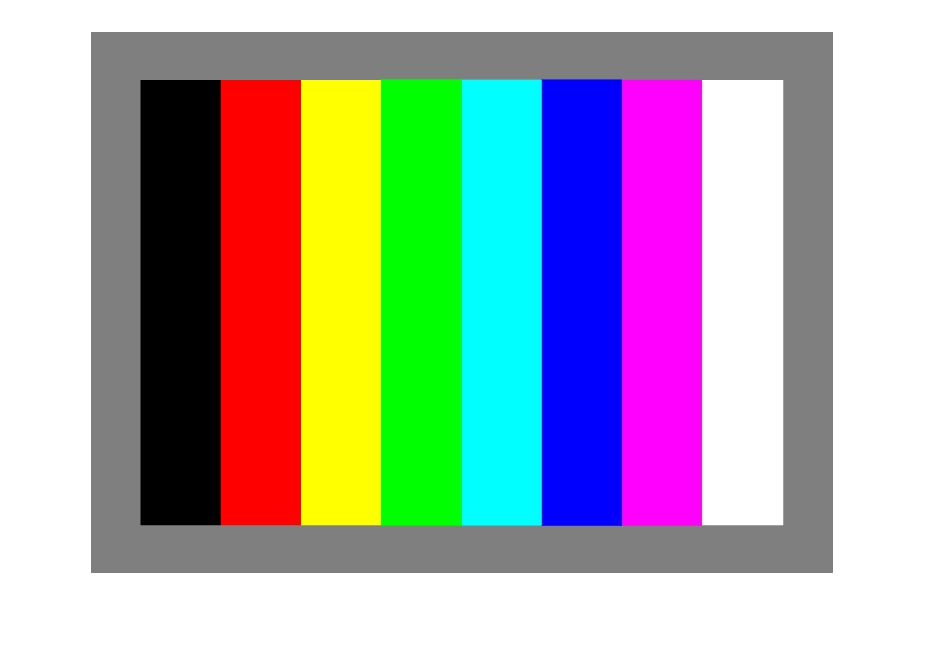

close; clc; clear all;
original_image1 = im2double(imread('Fig5-1.jpg'));
[M1,N1,Z1] = size(original_image1);
%split into RGB
for z = 1:Z1
    for x = 1:M1
        for y = 1:N1
            switch z
                case 1
                    Rd(x,y) = original_image1(x,y,z);
                case 2
                    Grn(x,y) = original_image1(x,y,z);
                case 3
                    Blu(x,y) = original_image1(x,y,z);
            end
        end
    end
end
%Convert RGB into HSI
for x = 1:M1
    for y = 1:N1
        R = Rd(x,y);
        G = Grn(x,y);
        B = Blu(x,y);
        Clrs = [R,G,B];%array to help determine minimum
        w = ((R-G)+(R-B))/(2*sqrt((R-G)^2 + ((R-B)*(G-B))));
        if (w>1)
            w = 1;
        elseif (w<-1)
            w = -1;
        end
        thta = acos(w);
        if (R==G && G==B)
            Hu(x,y) = 0;
            Sat(x,y) = 0;
        elseif (B > G)
            Hu(x,y) = (2*pi - thta)/(2*pi);
            Sat(x,y) = (1 - ((3/(R+G+B))*min(Clrs)));
        else
            Hu(x,y) = thta/(2*pi);
            Sat(x,y) = (1 - ((3/(R+G+B))*min(Clrs)));
        end
        Intn(x,y) = (R+G+B)/3;
    end
end
%convert HSI back to RGB
for x = 1:M1
    for y = 1:N1
        H = 360*Hu(x,y);
        S = Sat(x,y);
        I = Intn(x,y);
        if(S>1) 
            S=1;
        end
        if(I>1)
            I=1;
        end
        if (S == 0)
            r = I;
            g = I;
            b = I;
        else
            if ((H >= 0) && (H < 120))
                b = I*(1-S);
                r = I*(1 + (S*cosd(H) / cosd(60 - H)) );
                g = ((3*I) - (r+b));
            elseif ((H >= 120) && (H < 240))
                H = (H - 120);
                r = I*(1-S);
                g = I*(1 + (S*cosd(H) / cosd(60 - H) ));
                b = ((3*I) - (r+g));
            elseif ((H >= 240) && (H < 360))
                H = (H - 240);
                g = I*(1-S);
                b = I*(1 + (S*cosd(H) / cosd(60 - H) ));
                r = ((3*I) - (g+b));
            end
        end
        if r > 1
            r = 1;
        end
        if g > 1
            g = 1;
        end
        if b > 1
            b = 1;
        end
        Rnu(x,y) = r;
        Gnu(x,y) = g;
        Bnu(x,y) = b;
    end
end
%form new color images
for z = 1:Z1
    for x = 1:M1
        for y = 1:N1
            switch z
                case 1
                    new_image1a(x,y,z) = Hu(x,y);
                    new_image1b(x,y,z) = Rnu(x,y);
                case 2
                    new_image1a(x,y,z) = Sat(x,y);
                    new_image1b(x,y,z) = Gnu(x,y);
                case 3
                    new_image1a(x,y,z) = Intn(x,y);
                    new_image1b(x,y,z) = Bnu(x,y);
            end
        end
    end
end
imshow(original_image1);

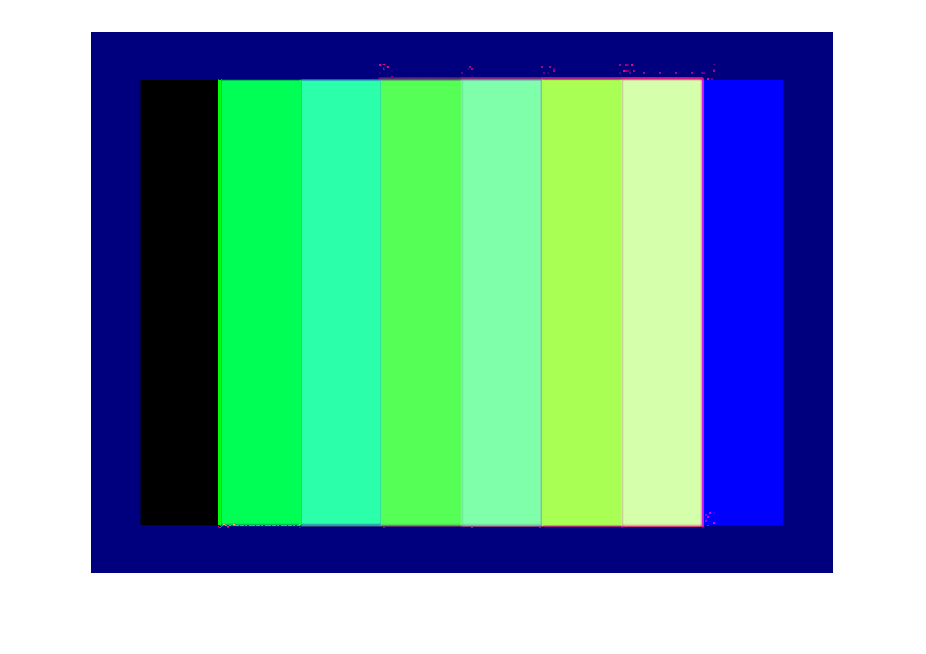

imshow(new_image1a);

% imwrite(new_image1a, 'Fig5-1HSI.jpg');
imshow(new_image1b);

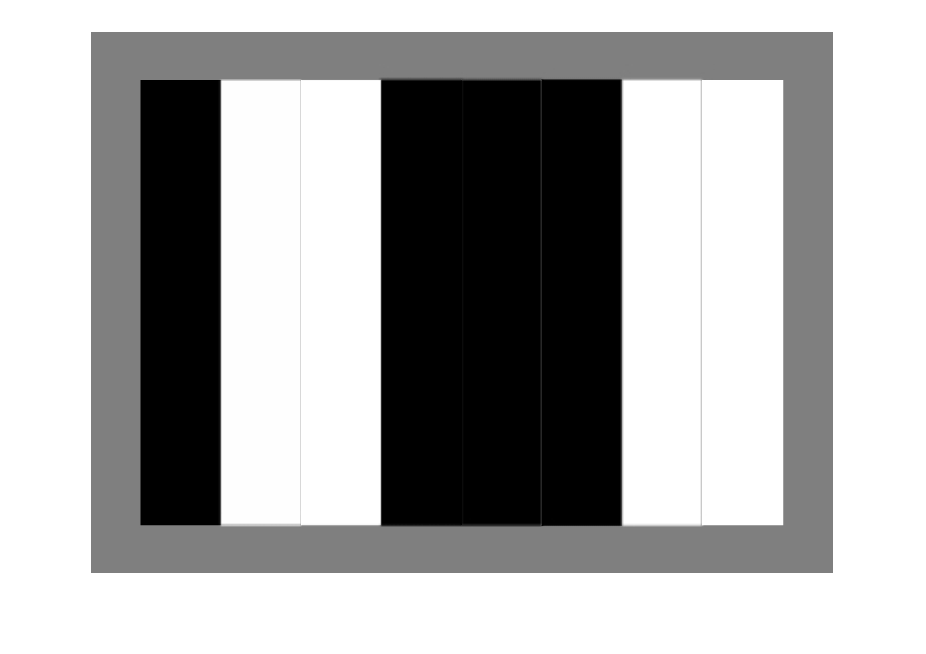

% imwrite(new_image1b, 'Fig5-1RGB.jpg');
imshow(Rd);

imshow(Rnu);

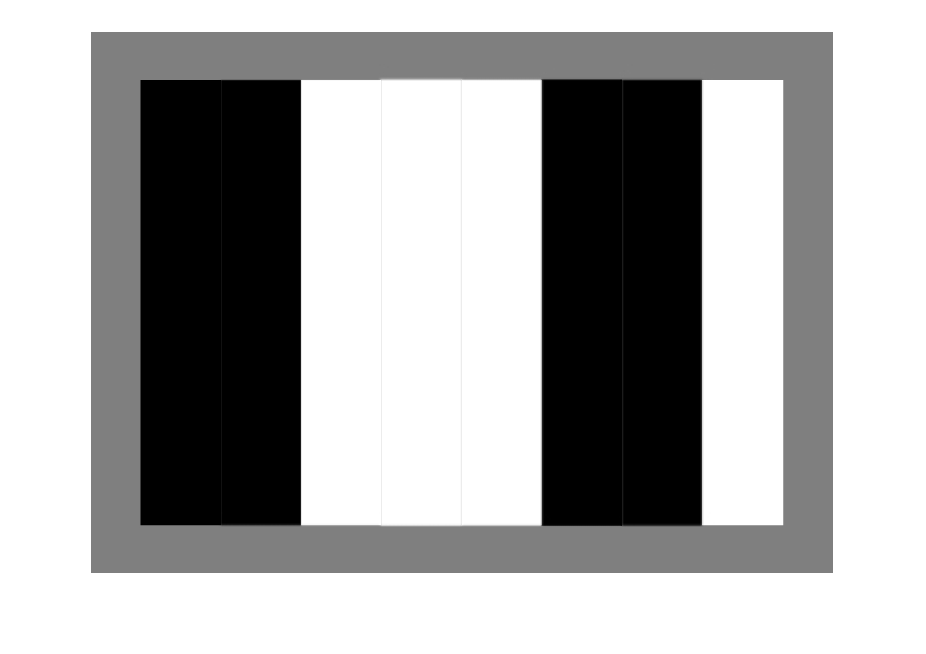

imshow(Grn);

imshow(Gnu);

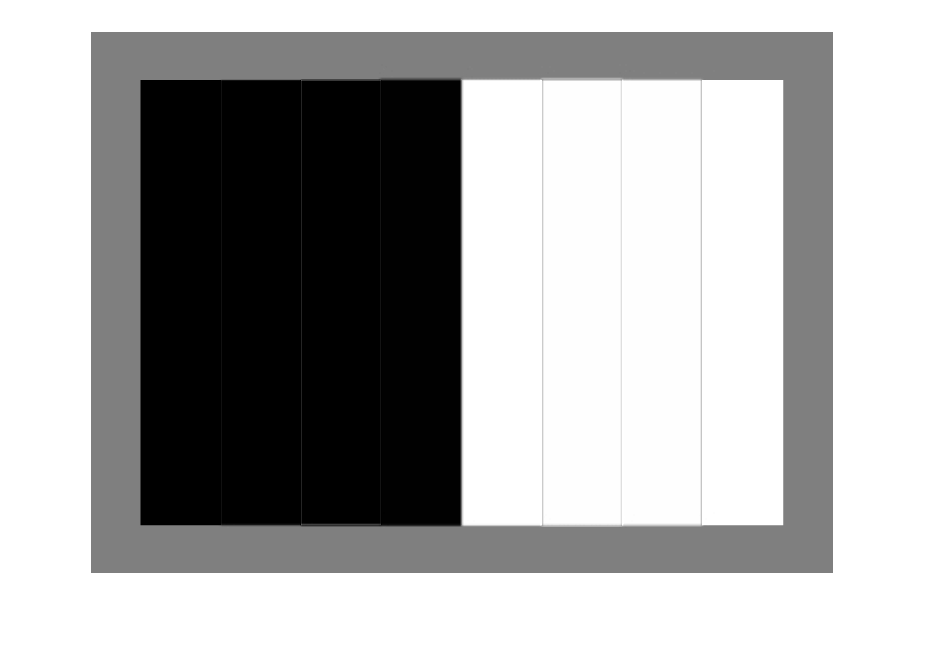

imshow(Blu);

imshow(Bnu);

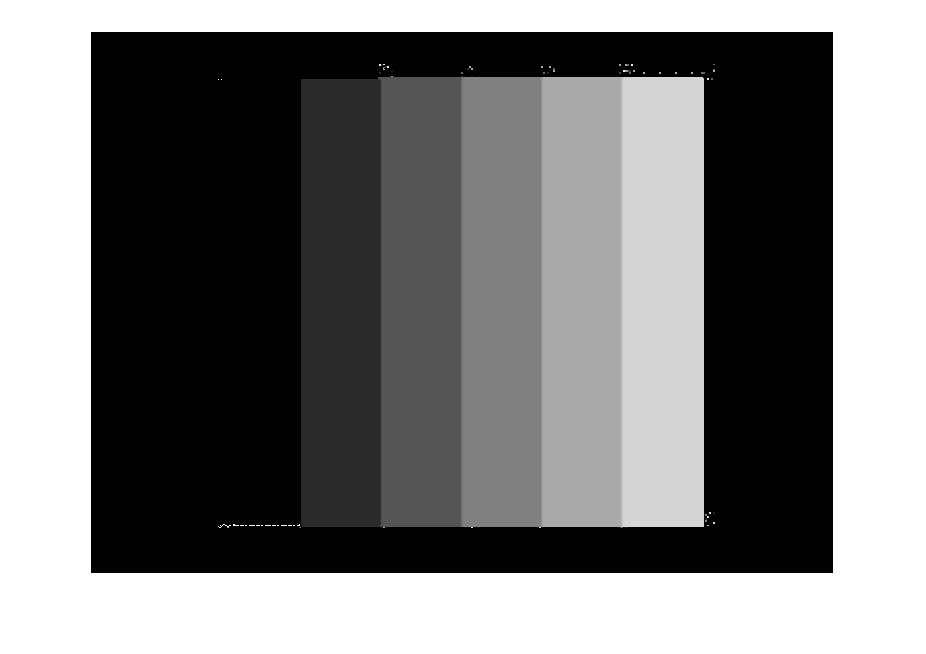

% imwrite(Rd, 'Fig5-1Red.jpg');
% imwrite(Grn, 'Fig5-1Green.jpg');
% imwrite(Blu, 'Fig5-1Blue.jpg');
imshow(Hu);

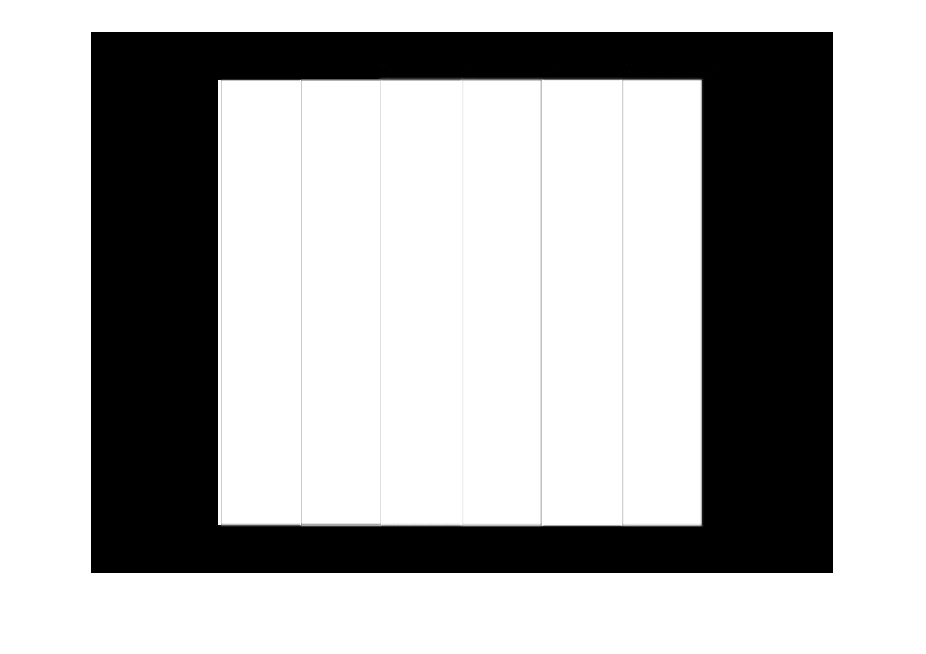

imshow(Sat);

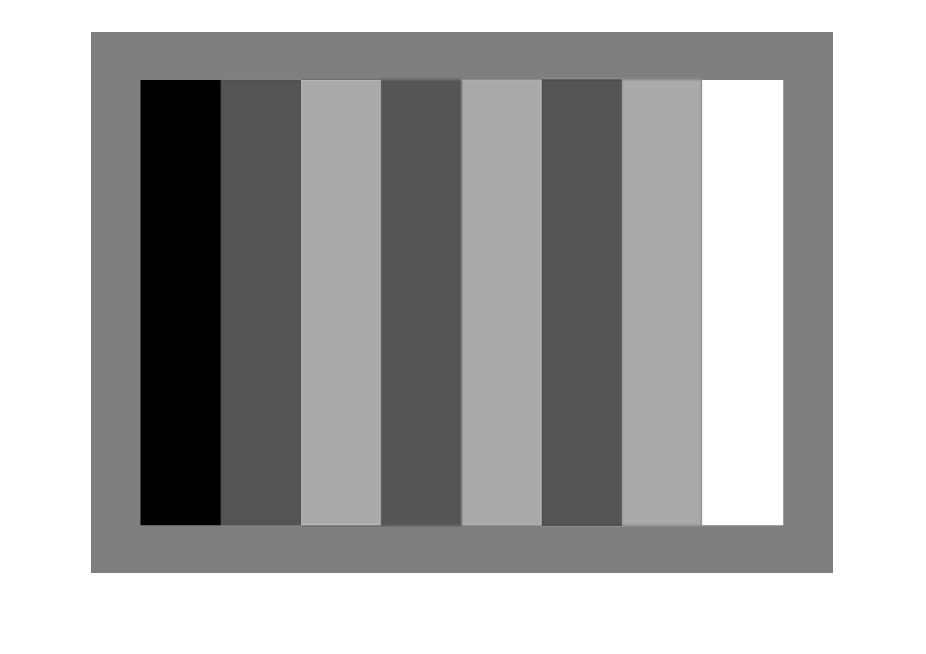

imshow(Intn);

% imwrite(Hu, 'Fig5-1Hue.jpg');
% imwrite(Sat, 'Fig5-1Saturation.jpg');
% imwrite(Intn, 'Fig5-1Intensity.jpg');